# Signal Design App

## Signal design app

Use [`SignalDesignApp`](matlab:SignalDesignApp) to define a signal trace and then set up either Simscape [PS Lookup Table (1D)](https://www.mathworks.com/help/releases/R2025a/simscape/ref/pslookuptable1d.html) block or Simulink [1-D Lookup Table](https://www.mathworks.com/help/simulink/slref/1dlookuptable.html) block. To design a signal trace, write a signal design matrix in the app. The app generates block parameters corresponding to the specified signal design matrix and can send them to a target block. The app also sends the signal design matrix as text to the Description property of the block, which the app can get later.

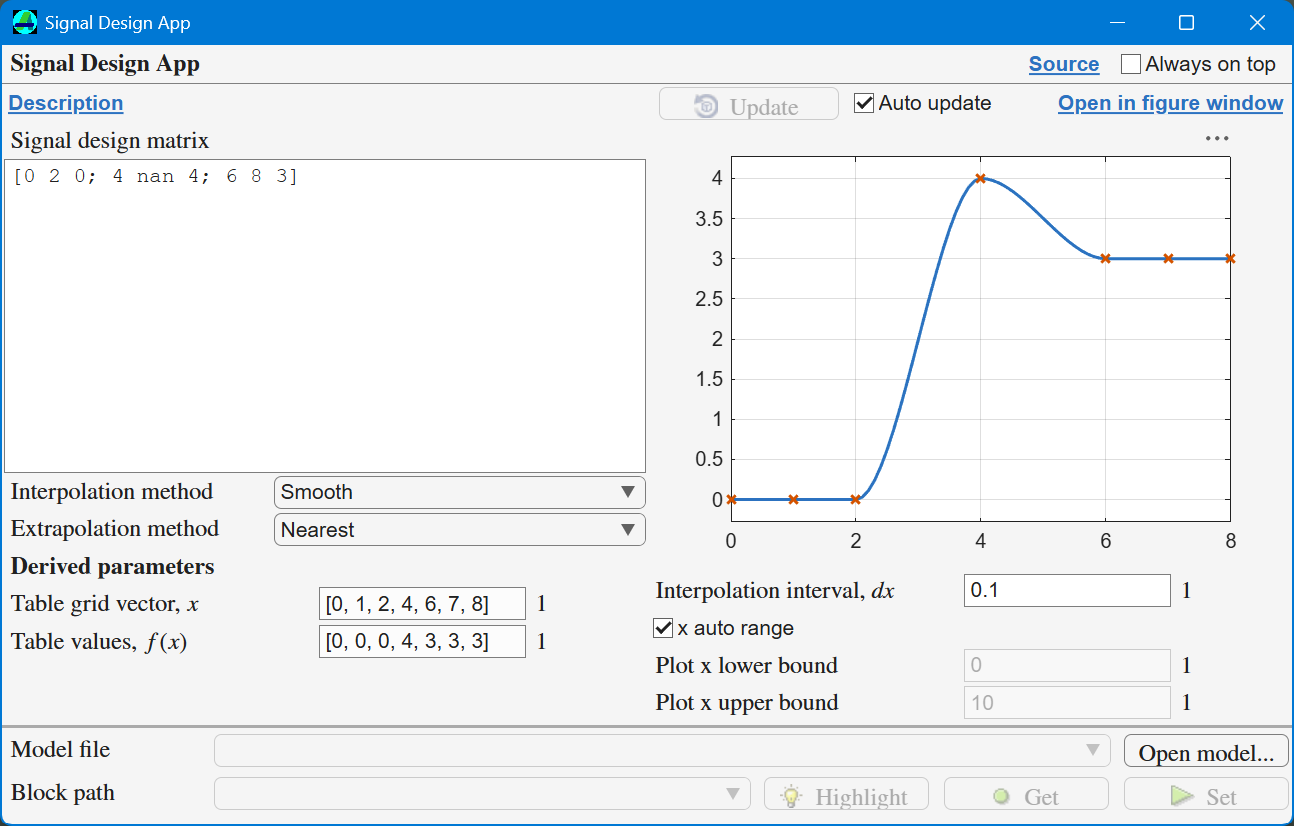

## Signal design matrix

A signal design matrix is an N-by-3 numeric matrix in the form of [x1, x2, y1; x3, x4, y2; ...] where each row represents a segment of a signal trace based on the following rules.

- The first column (x1, x3, ...) is the start point of a segment.

- The second column (x2, x4, ...) is the end point of a segment.

- The third column (y1, y2, ...) is the value of a segment between the start and end points.

- The second column can be NaN. In this case, the third column represents a value at the first-column point.

For example, a design matrix

design_matrix = [0 2 0; 4 nan 4; 7 9 3];

with smooth interpolation (modified Akima interpolation) defines a signal trace shown below. For flat segments between 0 and 2 (first row) and between 7 and 9 (third row), a mid-point is automatically added, which is required by the modified Akima interpolation to produce a flat segment.

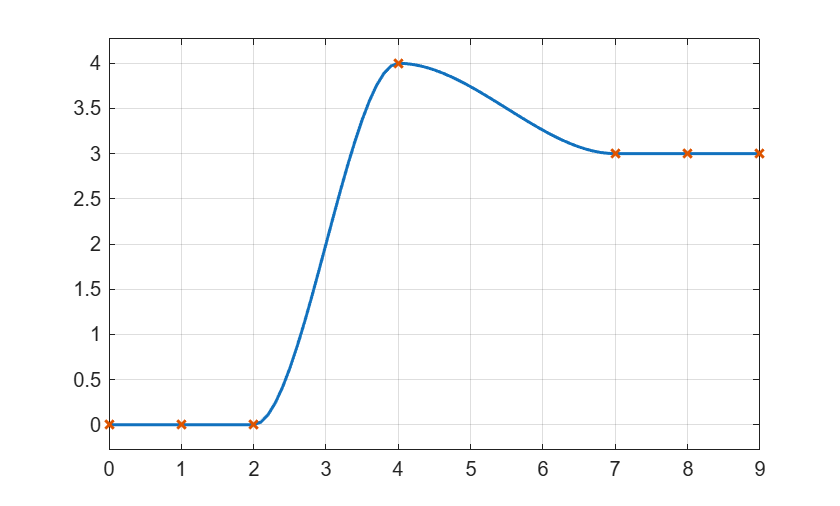

tt = mus1.SignalUtil.getVectorsFromSignalDesignMatrix(design_matrix);
mus1.SignalUtil.plotLookupTable1D(tt.X, tt.F)

A design matrix can be converted to standard two vectors used in **PS Lookup Table (1D) block**, one for **Table grid vector**, $x$.

disp(tt.X')

     0     1     2     4     7     8     9



And the other for **Table values**, $f\left(x\right)$.

disp(tt.F')

     0     0     0     4     3     3     3



These two vectors are **Breakpoints 1** and **Table data** in **1-D Lookup Table block**, respectively.

The signal design app shows these vectors as derived parameters. In the App, you can transfer these vector data to a PS Lookup Table (1D) block or a 1-D Lookup Table block by opening a model from the **Open model** button, selecting a block path from the **Block path** drop down, and clicking the **Set** button. If the block has the design matrix text in the Description block property, you can get it in the App by clicking the **Get** button.

## See also

- Cleve's corner: [Makima Piecewise Cubic Interpolation](https://blogs.mathworks.com/cleve/2019/04/29/makima-piecewise-cubic-interpolation/)

*Copyright 2025-2026 The MathWorks, Inc.*